# Propagation and Link-Budget Calculations.  In-Class Exercises

These exercises accompany the lectures for this unit and should be done at the end of each section.

## Problem 1:  Adding Noise and Measuring SNR

In this problem, we will simulate a simple cascade of two  receiver elements:

- An LNA with gain `GLna` and noise figure `NFLna`

- A mixer with unity gain and noise figure `NFmix`  

The received signal has power `Prx` and bandwidth `B`.

Prx = -80;     % RX power in dBm
NFLna = 6;     % Noise figure in the LNA in dB
GLna = 15;     % LNA gain in dB
NFmix = 13;    % mixer noise figure
B = 18e6;      % Bandwidth in Hz

Compute and print the effective noise figure.

% TODO
NFeff = 10*log10( 10.^(NFLna/10) + (10.^(NFmix/10)-1)/10.^(GLna/10) ); % dB

Assume the energy per sample in linear scale is `Es = Prx/B`.  Compute the SNR per sample, `EsN0,` including the effective noise figure.

% TODO
T = 290;
k=physconst('Boltzmann');
EkT = 10*log10(k*T);
N0 = EkT + NFeff;
Es = Prx - 30 - pow2db(B);
EsN0 = Es - N0;

We will now simulate this system.  Generate `nsym` QPSK modulation symbols and scale them to the correct energy per symbol. Place the results in a vector `s`.

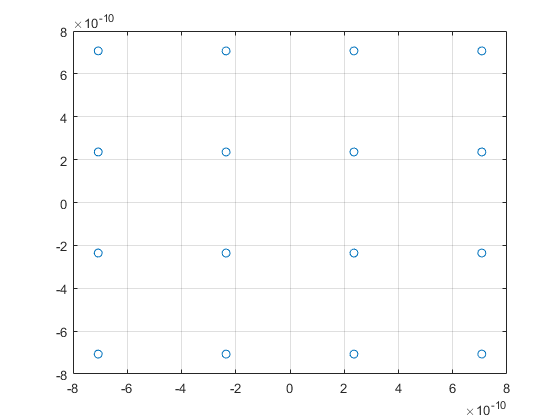

% Parameters
modRate = 4;    % num bits per symbol (4=16 QAM)
M = 2^modRate;  % QAM order
nsym = 10000;    % num symbols

% TODO
nbits = nsym*modRate;
bits = randi([0,1],nbits,1);
sym = qammod(bits,M,'InputType','bit','UnitAveragePower',true);

Es = db2pow(Prx - 30)/B;
s = sqrt(Es)*sym;

plot(real(s), imag(s), 'o');
grid();

Now simulate the receiver:

- Add the thermal noise of the LNA

- Scale the signal by the LNA gain 

- Add  the thermal noise of the mixer

For the thermal noise in the LNA and mixer use the `comm.ThermalNoise` class.  Store the results in a vector `r`.  Plot the received constellation.

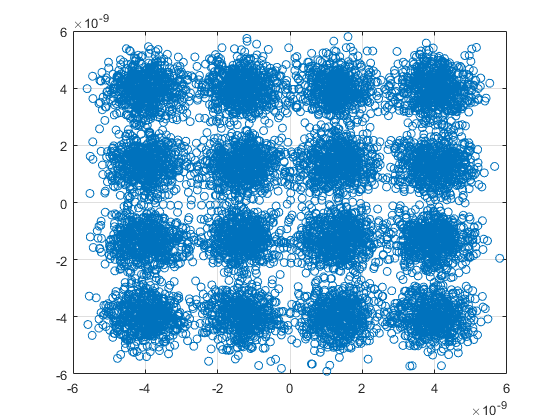

% TODO:

% Create a thermal noise object
tn_lna = comm.ThermalNoise('NoiseMethod', 'Noise figure', ...
                           'NoiseFigure', NFLna, 'Add290KAntennaNoise', true);
tn_mixer = comm.ThermalNoise('NoiseMethod', 'Noise figure', ...
                           'NoiseFigure', NFmix, 'Add290KAntennaNoise', true);
s1 = tn_lna.step(s);
G = db2mag(GLna);
r1 = G*s1;
r = tn_mixer.step(r1);

plot(real(r), imag(r), 'o');
grid();

Compute the SNR

where `G` is the receiver gain in linear scale and `E(.) denotes the average value.  Measure and print EsN0Meas and compare with the expected value.`

% TODO
EsN0Meas = 10*log10(mean(abs(G*s).^2)/(mean(abs(r-G*s).^2)));

In many cases, we do not know the gain `G, so it has to be estimated to compute the SNR. `  Suppose that we have a model:

where `G` is the unknown gain, and `N0` is the unknown noise variance.  We can estimate the gain and noise variance via linear regression:

This gives and SNR estimate:

where `rho` is the correlation coefficient:

Use this estimate to estimate the SNR.

% TODO
rho = real( abs(r'*s)^2/ (r'*r) / (s'*s) );
EsN0hat = 10*log10(rho/(1-rho));

## Problem 2.  Estimating the SNR Requirements for LTE

In this problem, we will see how the performance of a commercial LTE system comparse to the Shannon theory.  The LTE standard 36.942 provides a number of details of how to evaluate the performance of the system in various scenarios.  You can find any of the 3GPP standards by googling, e.g. "3GPP 36.942".  Below is a table from that document that shows the code performance as a function of the SNR for the uplink and downlink.     

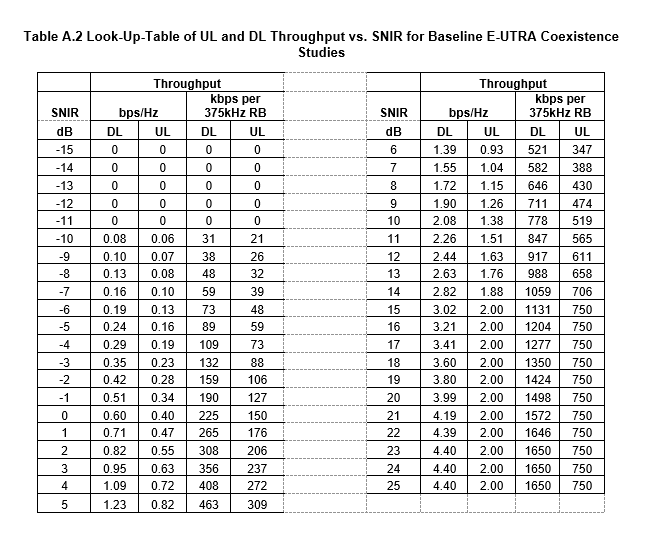

In the github folder, you will find an Excel file with this data.  You can read it via the command which will load the data into a table `T` .

T = readtable('lte_mcs.xlsx');
T = table2array(T);

Now, read the SNR and downlink spectral efficiency from the table into vectors `snr` and `se_dl`.  You can use the `table2array` function.  Plot the `se_dl` vs. `snr` .

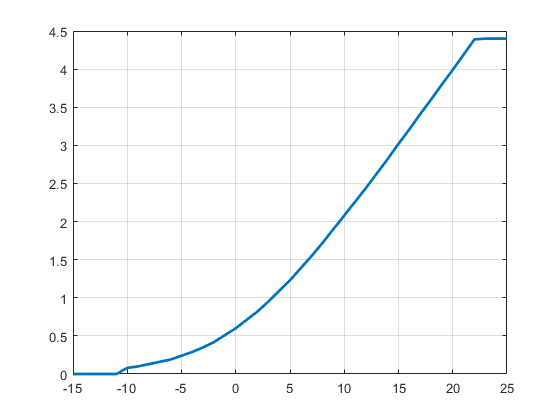

% TODO 
snr = T(:,1);
se_dl = T(:,2);
figure;
plot(snr,se_dl,'LineWidth',2);
grid();

On the same plot as above, plot the Shannon rate vs. SNR.  You should see that the LTE value is lower.

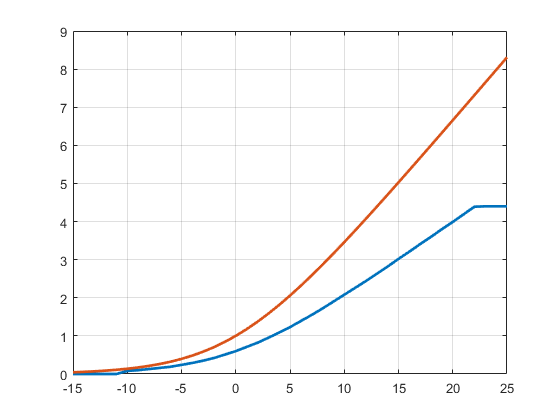

% TODO:
se_shannon = log2(1 + db2pow(snr));
hold on;
plot(snr,se_shannon,'LineWidth',2);

Fit a model for the LTE DL rate:

where `alpha` is a parameter that we will fit.  Fit this model using the data for SNR from -10 to 21 dB.  To fit a model of the form `y_i = alpha*x_i` , you can use the regression formula:

Print alpha.  Also add the line `se_dl_hat`  vs. `snr to` the previous plot.

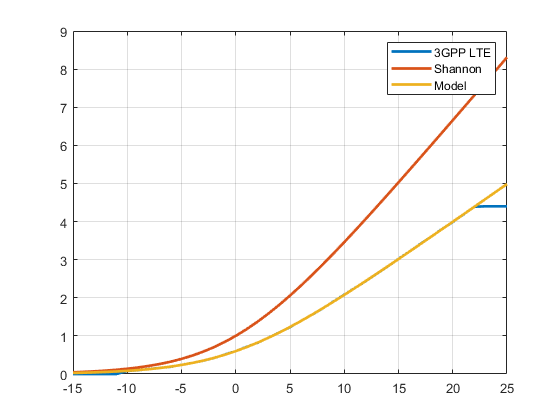

% TODO:
I = find((snr >= -10) & (snr <= 20));
x_s = log2(1+10.^(0.1*snr(I)));
y_s = se_dl(I);
alpha = sum(x_s.*y_s) / sum(x_s.^2);
se_dl_hat = alpha*log2(1 + 10.^(0.1*snr) );
hold on;
plot(snr,se_dl_hat,'LineWidth',2);
legend("3GPP LTE","Shannon","Model");

## Problem 3:  Simulating Path Loss Variations

Suppose the TX power is `Ptx `and the path loss can be modeled as a random variable as follows:

- The channel is either LOS or NLOS with probability `ProbLos` and `1-ProbLos, respectively.`

- If the channel is LOS, the path loss is lognormally distributed with mean `PLLos` and standard deviation `stdLos`.

- If the channel is NLOS, the path loss is lognormally distributed with mean `PLNlos` and standard deviation `stdNlos`.

Generate `n=10000` channel instances and plot the histogram of the received power.  You may use the MATLAB `histogram` function.

Ptx = 15;       % Tx power in dBm
ProbLos = 0.4;  % LOS probability
PLNlos = 80;    % Path loss for LOS (dB)
PLLos = 100;    % Path loss for NLOS (dB)
stdLos = 8;     % Path loss std dev for LOS (dB)
stdNlos = 4;     % Path loss std dev for LOS (dB)
n = 10000;      % number of samples

% TODO
%   Prx = ...
%   histogram(Prx, ...);

